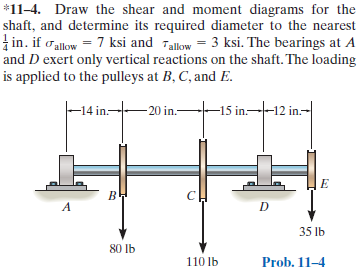

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-4P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-4P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

Dsol = default_struct('sigma', 'tau', 'limit');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('concentrated', 'force', -80*u.lbf, 14*u.in);
b = b.add('concentrated', 'force', -110*u.lbf, 34*u.in);
b = b.add('reaction', 'force', 'Rd', 49*u.in);
b = b.add('concentrated', 'force', -35*u.lbf, 61*u.in);
b.L = 61*u.in;

# section properties

D = sym('D', 'positive');
b.I(D) = sympi*(D/2)^4/4;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{320\,x\,\left(587478\,{\mathrm{in}}^{2}-403\,x^{2}\right)}{147\,{\text{D}}^{4}\,\text{E}\,\pi }\,\mathrm{lbf} & \text{ if }x\leq 14\,\mathrm{in}\\ \frac{320\,\left(11\,x^{3}+16464\,x^{2}\,\mathrm{in}-817974\,x\,{\mathrm{in}}^{2}+1075648\,{\mathrm{in}}^{3}\right)}{147\,{\text{D}}^{4}\,\text{E}\,\pi }\,\mathrm{lbf} & \text{ if }x\in \left(14\,\mathrm{in},34\,\mathrm{in}\right]\\ -\frac{640\,\left(x-49\,\mathrm{in}\right)\,\left(88\,x^{2}-7595\,x\,\mathrm{in}+75716\,{\mathrm{in}}^{2}\right)}{49\,{\text{D}}^{4}\,\text{E}\,\pi }\,\mathrm{lbf} & \text{ if }x\in \left(34\,\mathrm{in},49\,\mathrm{in}\right]\\ \frac{160\,\left(x-49\,\mathrm{in}\right)\,\left(343\,x^{2}-45962\,x\,\mathrm{in}+2450407\,{\mathrm{in}}^{2}\right)}{147\,{\text{D}}^{4}\,\text{E}\,\pi }\,\mathrm{lbf} & \text{ if }49\,\mathrm{in}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{320\,\left(195826\,{\mathrm{in}}^{2}-403\,x^{2}\right)}{49\,{\text{D}}^{4}\,\text{E}\,\pi }\,\mathrm{lbf} & \text{ if }x\leq 14\,\mathrm{in}\\ \frac{320\,\left(11\,x^{2}+10976\,x\,\mathrm{in}-272658\,{\mathrm{in}}^{2}\right)}{49\,{\text{D}}^{4}\,\text{E}\,\pi }\,\mathrm{lbf} & \text{ if }x\in \left(14\,\mathrm{in},34\,\mathrm{in}\right]\\ -\frac{640\,\left(264\,x^{2}-23814\,x\,\mathrm{in}+447871\,{\mathrm{in}}^{2}\right)}{49\,{\text{D}}^{4}\,\text{E}\,\pi }\,\mathrm{lbf} & \text{ if }x\in \left(34\,\mathrm{in},49\,\mathrm{in}\right]\\ \frac{160\,\left(343\,x^{2}-41846\,x\,\mathrm{in}+1567515\,{\mathrm{in}}^{2}\right)}{49\,{\text{D}}^{4}\,\text{E}\,\pi }\,\mathrm{lbf} & \text{ if }49\,\mathrm{in}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{4030\,x}{49}\,\mathrm{lbf} & \text{ if }x\leq 14\,\mathrm{in}\\ \frac{10\,\left(11\,x+5488\,\mathrm{in}\right)}{49}\,\mathrm{lbf} & \text{ if }x\in \left(14\,\mathrm{in},34\,\mathrm{in}\right]\\ -\frac{60\,\left(88\,x-3969\,\mathrm{in}\right)}{49}\,\mathrm{lbf} & \text{ if }x\in \left(34\,\mathrm{in},49\,\mathrm{in}\right]\\ 35\,\left(x-61\,\mathrm{in}\right)\,\mathrm{lbf} & \text{ if }49\,\mathrm{in}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{4030}{49}\,\mathrm{lbf} & \text{ if }x\leq 14\,\mathrm{in}\\ \frac{110}{49}\,\mathrm{lbf} & \text{ if }x\in \left(14\,\mathrm{in},34\,\mathrm{in}\right]\\ -\frac{5280}{49}\,\mathrm{lbf} & \text{ if }x\in \left(34\,\mathrm{in},49\,\mathrm{in}\right]\\ 35\,\mathrm{lbf} & \text{ if }49\,\mathrm{in}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra_vpa = vpa(ra, 5) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 82.245\,\mathrm{lbf}\\ \mathrm{Rd} & 142.76\,\mathrm{lbf} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

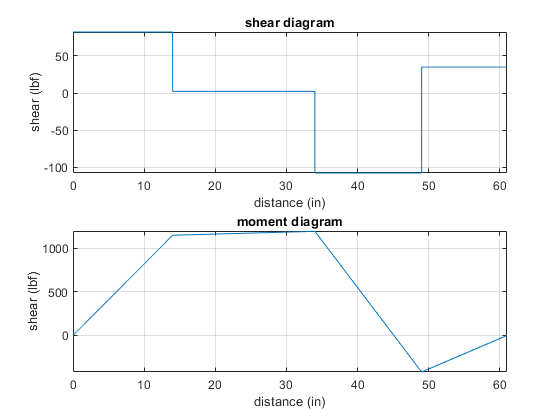

beam.shear_moment(m, v, [0 b.L], {'lbf' 'in'});

# maximum loads

M_max = m(34*u.in);
M_max_vpa = vpa(M_max, 6) %#ok<NASGU> 

$$M\_max\_vpa = 1196.33\,\mathrm{in}\,\mathrm{lbf}$$

V_max = -v(40*u.in);
V_max_vpa = vpa(V_max, 5) %#ok<NASGU> 

$$V\_max\_vpa = 107.76\,\mathrm{lbf}$$

# design for normal stress

sigma_allow = 7*u.ksi;
C(D) = D/2;
sigma_max = rewrite(M_max*C/b.I, [u.ksi u.in])

$$sigma\_max(D) = \frac{46896}{1225\,{\text{D}}^{3}\,\pi }\,{\mathrm{in}}^{3}\,\mathrm{ksi}$$

Dsol.sigma = simplify(solve(sigma_allow == sigma_max));
Dsol_sigma = vpa(Dsol.sigma, 3) %#ok<NASGU> 

$$Dsol\_sigma = 1.2\,\mathrm{in}$$

# design for shear stress

tau_allow = 3*u.ksi;
Q_max(D) = (4*(D/2)/(3*sympi))*(sympi*(D/2)^2/2);
t_min(D) = D;
tau_max = rewrite(V_max*Q_max/(b.I*t_min), [u.ksi u.in])

$$tau\_max(D) = \frac{704}{1225\,{\text{D}}^{2}\,\pi }\,{\mathrm{in}}^{2}\,\mathrm{ksi}$$

Dsol.tau = simplify(solve(tau_allow == tau_max));
Dsol_tau = vpa(Dsol.tau, 2) %#ok<NASGU> 

$$Dsol\_tau = 0.25\,\mathrm{in}$$

# minimum diameter value

Dsol_vals = [Dsol.sigma Dsol.tau];
in_range = isAlways(sigma_max(Dsol_vals) <= sigma_allow & ...
                    tau_max(Dsol_vals) <= tau_allow);
Dsol.limit = Dsol_vals(in_range);
Dsol_limit = vpa(Dsol.limit, 3) %#ok<NASGU> 

$$Dsol\_limit = 1.2\,\mathrm{in}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear M_max_vpa V_max_vpa;
clear Dsol_sigma;
clear Dsol_tau;
clear Dsol_vals Dsol_limit;